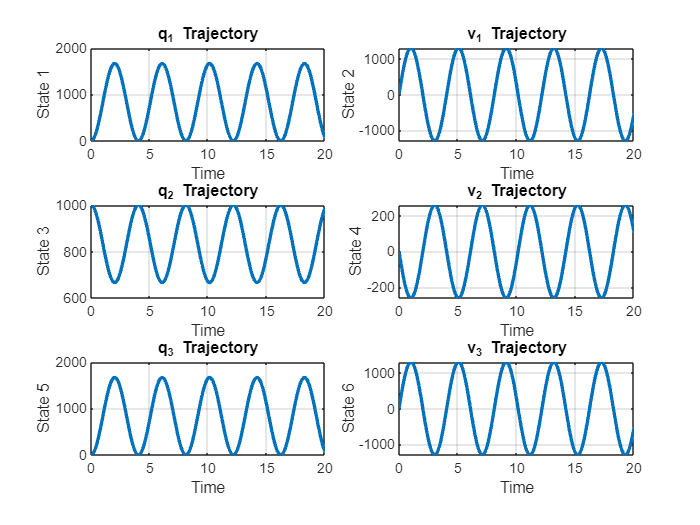

addpath("Functions\")
[A,B,C,D] = systemDynamics;
x0 = [-1,0,1000,0,-1,0];
[F,G,H,L,h,dominantFrequency] = discretize(x0(1),x0(3),x0(5));


% Simulation time
t_sim = 0:0.1:20; 

odefun_open = @(t,x) A*x;
[t_sim, x_open] = ode45(odefun_open, t_sim, x0);

% Plot the state trajectories
figure
j=1;
for i = 1:6
    subplot(3, 2, i);
    plot(t_sim, x_open(:, i), 'LineWidth', 2);
    if mod(i,2) == 0
        title(['v_', num2str(j), ' Trajectory']);
        j=1+j;
    else
        title(['q_', num2str(j), ' Trajectory']);
    end
    xlabel('Time');
    ylabel(['State ', num2str(i)]);
    grid on;
    
end

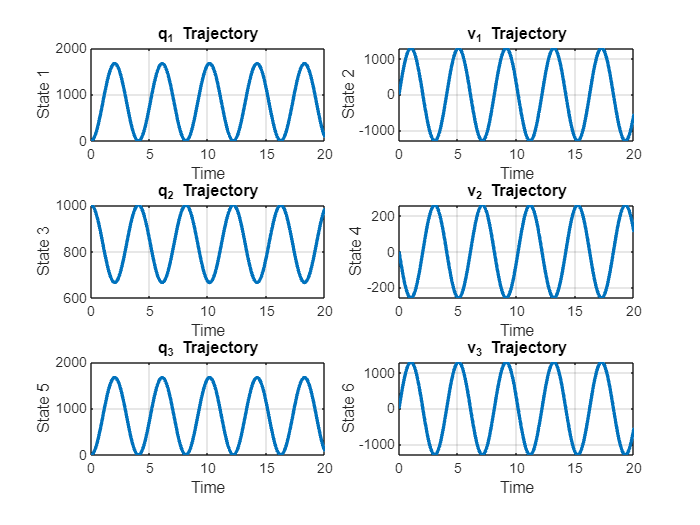

odefun1 = @(t, x) F* x; 

t_sim = 0:h:20;

x_disc= zeros(length(t_sim), size(F, 1));
x_disc(1, :) = x0;

for i = 2:length(t_sim)
    x_disc(i, :) = odefun1(t_sim(i), x_disc(i-1, :)');
end

figure
j=1;
for i = 1:6
    subplot(3, 2, i);
    plot(t_sim, x_disc(:, i), 'LineWidth', 2); hold on;
    if mod(i,2) == 0
        title(['v_', num2str(j), ' Trajectory']);
        j=1+j;
    else
        title(['q_', num2str(j), ' Trajectory']);
    end
    xlabel('Time');
    ylabel(['State ', num2str(i)]);
    grid on;
    
end

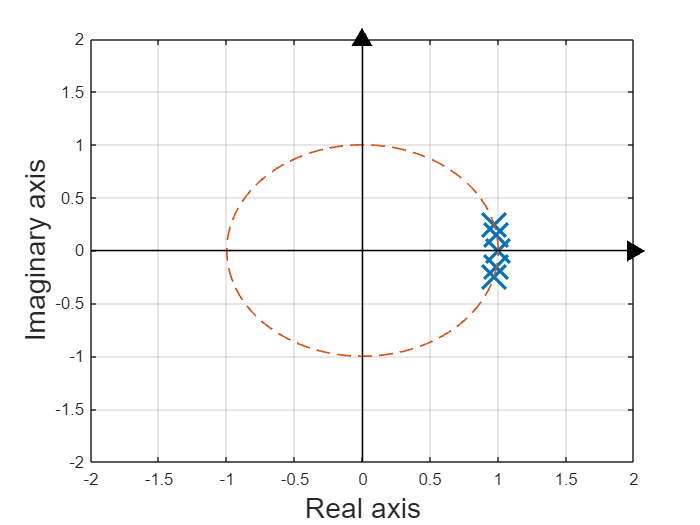


% Plot the poles using pzmap
figure;
[p,z]=pzmap(F,G,H,L);
x = real(p);
y = imag(p);

theta = linspace(0, 2*pi, 100); % Generate 100 points around the circle
rho_x = cos(theta);
rho_y = sin(theta);

eig_DT_x = real(eig_DT);
eig_DT_y = imag(eig_DT);

figure;
plot(x, y, 'x', 'MarkerSize', 20, 'MarkerFaceColor', 'b','LineWidth',2);
plot(eig_DT_x, eig_DT_y, 'x', 'MarkerSize', 20, 'MarkerFaceColor', 'b','LineWidth',2);
xlabel('Real axis','FontSize',17);
ylabel('Imaginary axis','FontSize',17);
grid on;
hold on;
plot(rho_x,rho_y,'LineStyle','--','Linewidth',1);
% Plot x-axis
plot([-2, 2], [0, 0], 'k-', 'LineWidth', 1);

% Plot y-axis
plot([0, 0], [-2, 2], 'k-', 'LineWidth', 1);
plot(2, 0, '>', 'MarkerSize', 8, 'MarkerFaceColor','black','MarkerEdgeColor','black','LineWidth',2);
plot(0, 2, '^', 'MarkerSize', 8, 'MarkerFaceColor','black','MarkerEdgeColor','black','LineWidth',2);